## Part 1: Fourier Series

# 1.1.a & 1.1.b

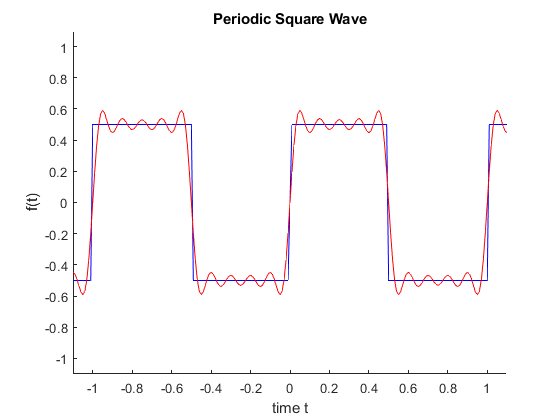

t = -1.1:.01:1.1;
T = 2*pi; % integrate from 0 to 2pi
n = 0:10; 
c0 = 0; %average energy is 0
cn = [0 -j*2/1/pi 0 -j*2/3/pi 0 -j*2/5/pi 0 -j*2/7/pi 0 -j*2/9/pi 0];
cn = cn ./2;
% y = 2/pi*sin(t)+2/3/pi*sin(3*t)+2/5/pi*sin(5*t)+2/7/pi*sin(7*t)+2/9/pi*sin(9*t);
% c0 is the average of the whole signal, which is 0.
% cn = 1/(2*n*pi)*cos(n*t);
c_n = conj(cn);

Wn = exp(1j * 2 * pi / T *2 * pi * t'*n); %Wn modified to fit the x axis required
W_n = conj(Wn);
gN = c0 + Wn * cn.' + W_n*c_n.';

gN_1 = gN;

f = 0.5*sign(sin(2*pi*t));
f_1 = f;
f = f.';
hold on
plot(t, f, 'blue')
plot(t, gN, 'red')
axis([-1.1, 1.1, -1.1, 1.1]); title('Periodic Square Wave'); xlabel('time t'); ylabel('f(t)');
hold off

# 1.1.c

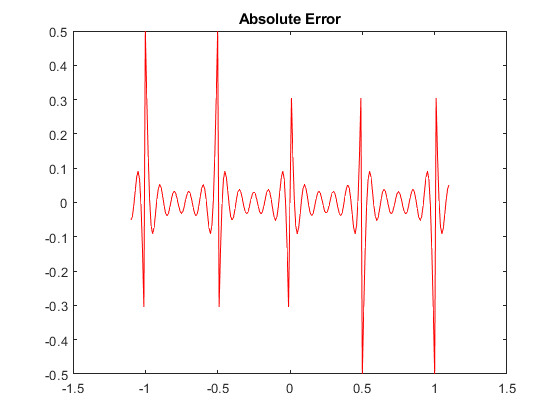



abs_error = f - gN;

plot (t, abs_error, 'red');
title('Absolute Error')

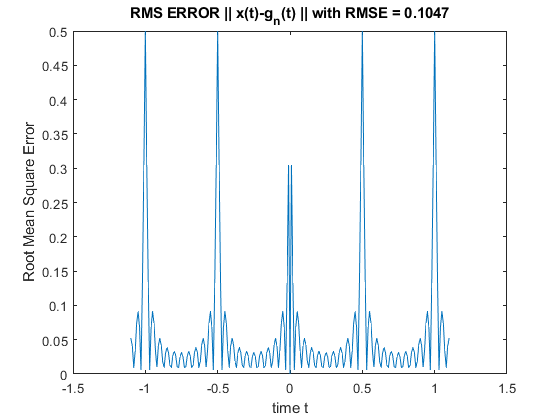


rmse = sqrt(sum(abs(f-gN).^2)/length(f));

plot(t, sqrt((f - gN).^2));
str = sprintf('RMS ERROR || x(t)-g_n(t) || with RMSE = %6.4f', rmse);
title(str);
xlabel('time t'); ylabel('Root Mean Square Error');

# 1.1.d

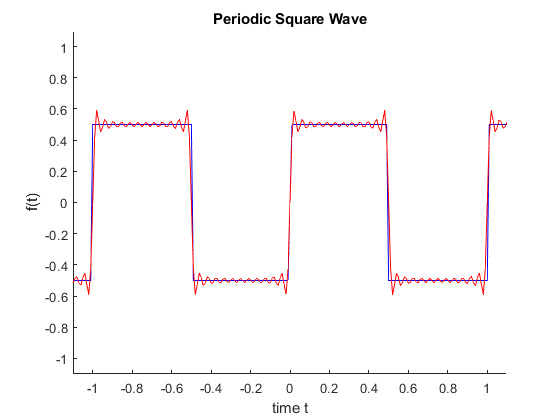

figure()
t = -1.1:.01:1.1;
T = 2*pi; % integrate from 0 to 2pi
n = 0:23; 
c0 = 0; %average energy is 0
cn = [0 -j*2/1/pi 0 -j*2/3/pi 0 -j*2/5/pi 0 -j*2/7/pi 0 -j*2/9/pi 0 -j*2/11/pi 0 -j*2/13/pi 0 -j*2/15/pi 0 -j*2/17/pi 0 -j*2/19/pi 0 -j*2/21/pi 0 -j*2/23/pi];
cn = cn ./2;
c_n = conj(cn);

Wn = exp(1j * 2 * pi / T *2 * pi * t'*n); %Wn modified to fit the x axis required
W_n = conj(Wn);
gN = c0 + Wn * cn.' + W_n*c_n.';


f = 0.5*sign(sin(2*pi*t));
f = f.';
hold on
plot(t, f, 'blue')
plot(t, gN, 'red')
axis([-1.1, 1.1, -1.1, 1.1]); title('Periodic Square Wave'); xlabel('time t'); ylabel('f(t)');
hold off


rmse = sqrt(sum(abs(f-gN).^2)/length(f))

rmse = 0.0739

%24 terms are required before the RMSE falls below 0.075


# 1.2.a

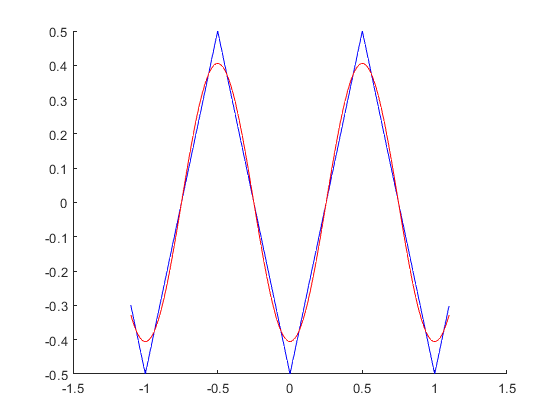

figure()
t = -1.1:.01:1.1;
T = 2*pi; % integrate from 0 to 2pi
n = 0:10; 
c0 = 0; %average energy is -0.25
cn = zeros([1 11]);
for k = 1:2:10
    cn(k+1) = -1*(1 - (-1).^k)/pi.^2 / k.^2;
end

% set new n and cn to find the minimum number of terms for rmse to be below
%0.05
cn = cn(1:2);
n = 0:1;
c_n = conj(cn);

Wn = exp(1j * 2 * pi / T *2 * pi * t'*n); %Wn modified to fit the x axis required
W_n = conj(Wn);
gN = c0 + Wn * cn.' + W_n*c_n.';


f = 0.5*sawtooth(2*pi*t,1/2);
f = f.';
hold on
plot(t, f, 'blue')
plot(t, gN, 'red')
%axis([-1.1, 1.1, -1.1, 1.1]); title('Periodic Triangle Wave'); xlabel('time t'); ylabel('f(t)');
hold off

rmse = sqrt(sum(abs(f-gN).^2)/length(f))

rmse = 0.0355

%obviously the periodic triangular signal converges more rapidly, as a sine
%wave is already close to a triangle wave. Even with one term, the RMSE is
%below .05.


# 1.3 - Not Done

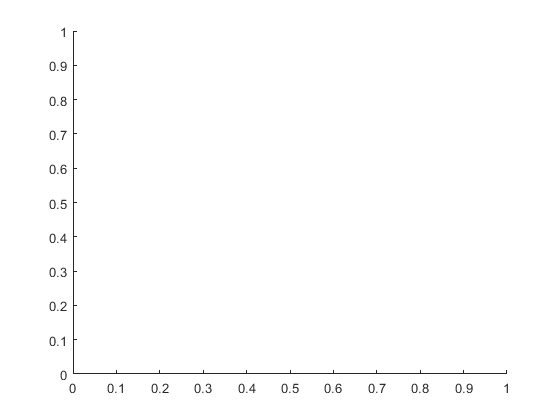

figure()
t = 0:5;
%t.^2 .* (5 - abs(t)).*exp(-1+cos(sin(pi.*t)))./(2-exp(-abs(t-2.5)));
x = @(t) t.^2 .* (5 - abs(t)).*exp(-1+cos(sin(pi.*t)))./(2-exp(-abs(t-2.5)));

q = integral(x, 0, 5);

%an = (2/5) * int(cos(n*pi*t))
hold on
%plot(t, x)
%plot([0, 5],[cn,cn])
hold off


% what fucking pdf



# 1.4

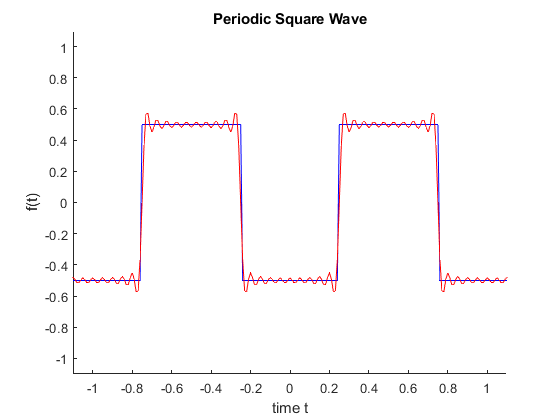

figure()
t = -1.1:.01:1.1;
T = 2*pi; % integrate from 0 to 2pi
n = 0:20; 
c0 = 0; %average energy is 0
cn = zeros([1 21]);
for k = 1:2:20
    cn(k+1) = -(1/pi/k)*((-1).^((k-1)/2));
end


c_n = conj(cn);

Wn = exp(1j * 2 * pi / T *2 * pi * (t)'*n); %Wn modified to fit the x axis required
W_n = conj(Wn);
gN = c0 + Wn * cn.' + W_n*c_n.';

f = 0.5*sign(sin(2*pi*(t-.25)));
f = f.';
hold on
plot(t, f, 'blue')
plot(t, gN, 'red')
axis([-1.1, 1.1, -1.1, 1.1]); title('Periodic Square Wave'); xlabel('time t'); ylabel('f(t)');
hold off

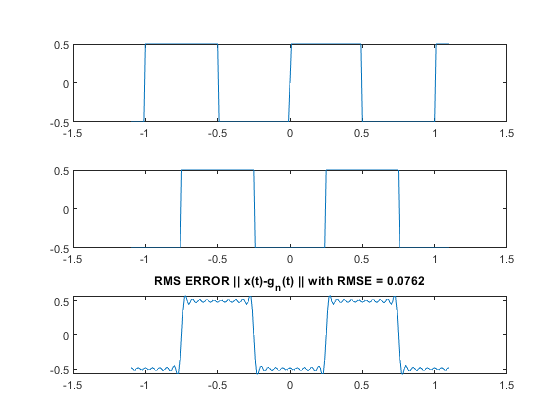



subplot(3,1,1)
plot(t, f_1)
subplot(3,1,2)
plot(t, f)
subplot(3,1,3)
plot(t, gN)
rmse = sqrt(sum(abs(f-gN).^2)/length(f));
str = sprintf('RMS ERROR || x(t)-g_n(t) || with RMSE = %6.4f', rmse);
title(str);

# 1.5 - Not Done

figure()
t = -1/2:1/100:1/2;
f = abs(cos(pi*t));

plot(t, f)

T = 0.5

T = 0.5000

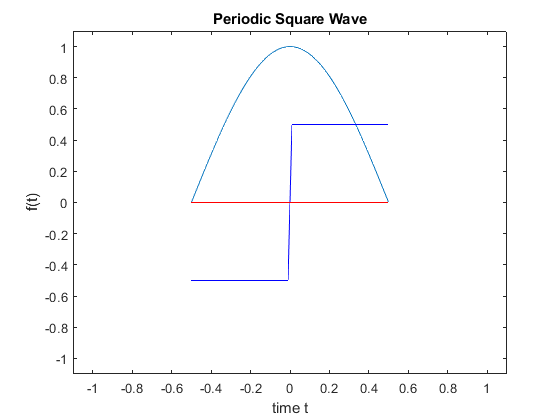

n = 0:10; 
c0 = 0; %average energy is 0
cn = zeros([1 11]);
for k = 1:2:10
    cn(k+1) = 0;
end
%%cn(0) = c0
% y = 2/pi*sin(t)+2/3/pi*sin(3*t)+2/5/pi*sin(5*t)+2/7/pi*sin(7*t)+2/9/pi*sin(9*t);
% c0 is the average of the whole signal, which is 0.
% cn = 1/(2*n*pi)*cos(n*t);
c_n = conj(cn);

Wn = exp(1j * 2 * pi / T *2 * pi * t'*n); %Wn modified to fit the x axis required
W_n = conj(Wn);
gN = c0 + Wn * cn.' + W_n*c_n.';

gN_1 = gN;

f = 0.5*sign(sin(2*pi*t));
f_1 = f;
f = f.';
hold on
plot(t, f, 'blue')
plot(t, gN, 'red')
axis([-1.1, 1.1, -1.1, 1.1]); title('Periodic Square Wave'); xlabel('time t'); ylabel('f(t)');
hold off

## Part 2.1

figure()
% indices less than 1 are all zeros
a = LTI_a()

a =     0.5000    2.0000    5.5000    9.0000


b = LTI_b()

b =     2.0000    5.6000   10.4800   16.3840


c = LTI_c()

c =          0    2.0000    5.6000   10.4800


## Part 2.2

% (a)
n = [1:1:6];
ny = 0:5;
x(n)= (-1).^n;

y(1) = x(1);
y(2) = x(2) + 0.5*x(1);
y(3) = x(3) + 0.5*x(2) - 2*x(1);

for n = 4:6
    y(n) = x(n) + 0.5*x(n-1) - 2*x(n-2) + 0.75*x(n-3);
end
h = [1,0.5,-2,0.75];
y = filter(h,1,x);
stem(ny,y);

%(b)

x1 = zeros(1,9);
for n = 1:length(x)
    x1(n) = x(n);
end

y1 = filter(h,1,x1);
yconv = conv(h,x);

% difference between the y1 - yconv is all zeros
y1-yconv

%(c)
n = [0:1:5];
h = n;
x = (-1).^n;

y = filter(h, 1, x);

figure();
hold on;
subplot(2,2,1); 
stem(n,h);
xlabel('n'); ylabel('h');

subplot(2,2,2);
stem(n, y);
xlabel('n'); ylabel('y');
hold off;

 
n1 = [-5:1:0];


% h1 needs to be shifted n-5, but arrays cannot have negative or zero index 
h1 = h;

%y1 is same as y... for n1, which is from -5 to 0. It's just shifted to the
%left...

figure();

hold on;
subplot(2,2,1); 
stem(n1,h1);
xlabel('n1'); ylabel('h1');

subplot(2,2,2);
stem(n1, y);
xlabel('n1'); ylabel('y1');
hold off;

# 3.1

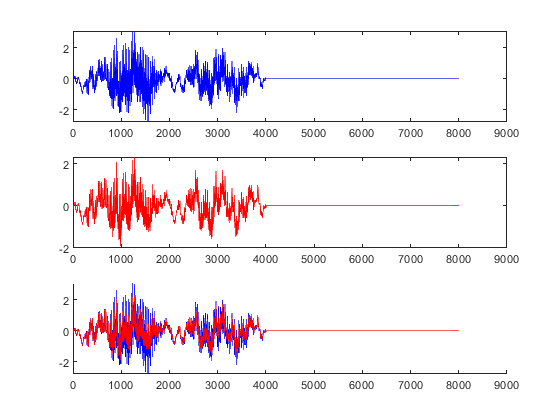

figure()
load mtlb.mat
x = mtlb;
%sound(x,Fs);

x = zeros(8002,1);

for n = 1:4001
    x(n) = mtlb(n);
end

Nx = 1:8002;
D = 2750;

windowSize = 5;
y = filter(ones(1,windowSize)/windowSize,1,x);

subplot(3,1,1)
plot(Nx, x, "blue")
subplot(3,1,2)
plot(Nx, y, "red")
subplot(3,1,3)
hold on
plot(Nx, x, "blue")
plot(Nx, y, "red")
hold off

# 4.1

n = [0:1:100];

%DTFT function
x = x.*exp (-1 *j *w*n);

# 5.1a

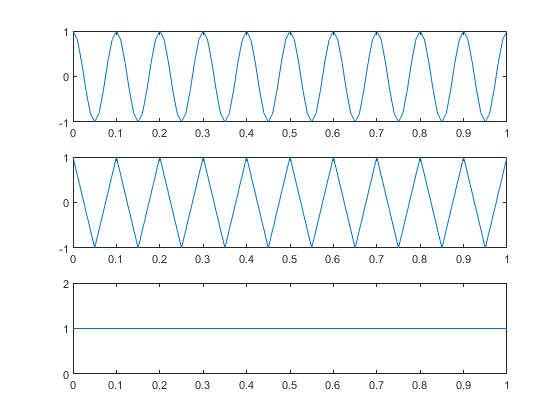

figure()
t1 = 0:1/100:1;
t2 = 0:0.05:1;
t3 = 0:0.1:1;


x_1 = cos(20*pi*t1);
x_2 = cos(20*pi*t2);
x_3 = cos(20*pi*t3);

subplot(3,1,1);
plot(t1, x_1)
subplot(3,1,2);
plot(t2, x_2)
subplot(3,1,3);
plot(t3, x_3)


% frequency is obviously 10hz


# 5.1b

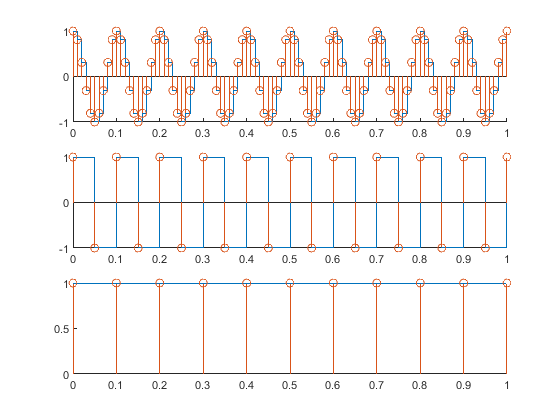

figure()

subplot(3,1,1);
hold on
stairs(t1, x_1);
stem(t1, x_1);
hold off


subplot(3,1,2);
hold on
stairs(t2, x_2);
stem(t2, x_2);
hold off
subplot(3,1,3);
hold on
stairs(t3, x_3);
stem(t3, x_3);
hold off


% frequency is obviously 10hz

# 5.1c

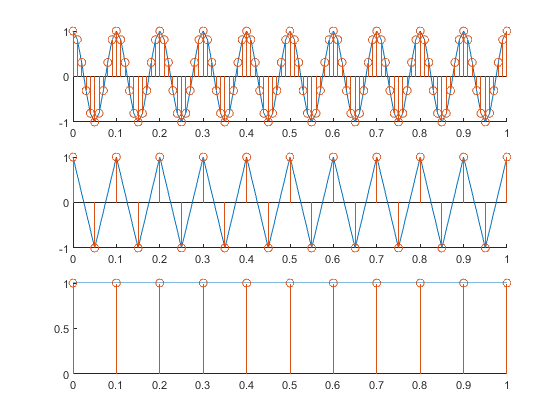

figure()

subplot(3,1,1);
hold on
plot(t1, x_1);
stem(t1, x_1);
hold off
subplot(3,1,2);
hold on
plot(t2, x_2);
stem(t2, x_2);
hold off
subplot(3,1,3);
hold on
plot(t3, x_3);
stem(t3, x_3);
hold off


% again, frequency is obviously 10hz


# 5.1d

figure()

t = 0:0.01:1;
xa = cos(20*pi*t); 
x_1_spl = spline(t1,x_1, t1);
x_2_spl = spline(t2,x_2, t2);
x_3_spl = spline(t3,x_3, t3);

subplot(3,1,1);
hold on
plot(t1,x_1); 
stem(t1,x_1_spl);
hold off

subplot(3,1,2);
hold on
plot(t2,x_2); 
stem(t2,x_2_spl);
hold off

subplot(3,1,3);
hold on
plot(t3,x_3); 
stem(t3,x_3_spl);
hold off


% again, frequency is obviously 10hz

# 5.1e

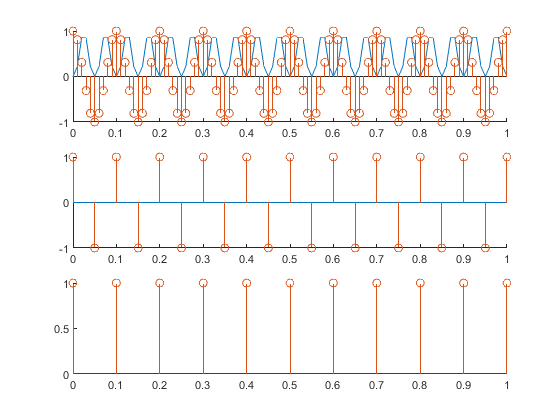

figure()

y_1 = sinc(x_1);
y_2 = sinc(x_2);
y_3 = sinc(x_3);

subplot(3,1,1);
hold on
plot(t1,y_1); 
stem(t1,x_1);
hold off

subplot(3,1,2);
hold on
plot(t2,y_2); 
stem(t2,x_2_spl);
hold off

subplot(3,1,3);
hold on
plot(t3,y_3); 
stem(t3,x_3);
hold off


% again, frequency is obviously 10hz


# 5.1f

%It appears that cubic spline and first order hold produce very similar
%results. Zero order hold creates a stair pattern. Sinc is odd, with the

%signals x2 and x3 creating a straight line.

# Functions

function a = LTI_a()
    x = [1:1:4];
    for n = 1:4
        if(n <= 1)
            a(n) = 0.5 * x(n);
        elseif(n <= 2)
            a(n) = 0.5 * x(n) + x(n-1); 
        else
            a(n) = 0.5 * x(n) + x(n-1) + 2*x(n-2);
        end
    end
end

function b = LTI_b()
    x = [1:1:4];
    for n = 1:4
        if(n <= 1)
            b(n) =  2* x(n);
        else
            b(n) = 0.8 * b(n-1) + 2* x(n);
        end
    end
end

function c = LTI_c()
    x = [1:1:4];
    for n = 1:4
        if(n <= 1)
            c(n) =  0;
        else
            c(n) = 0.8 * c(n-1) + 2* x(n-1);
        end
    end
end
